## Estimation

#### 1. Understand the model structure:

First of all, we collect the input and output measurements and then visualize the acquired signals on the plot below. I chose to plot the first 1000 signals' samples for convenience. Considering the fact that the input is available for us, we know that the "true" system that describes the relationship between the input and the output is the **FIR model** of some order. 

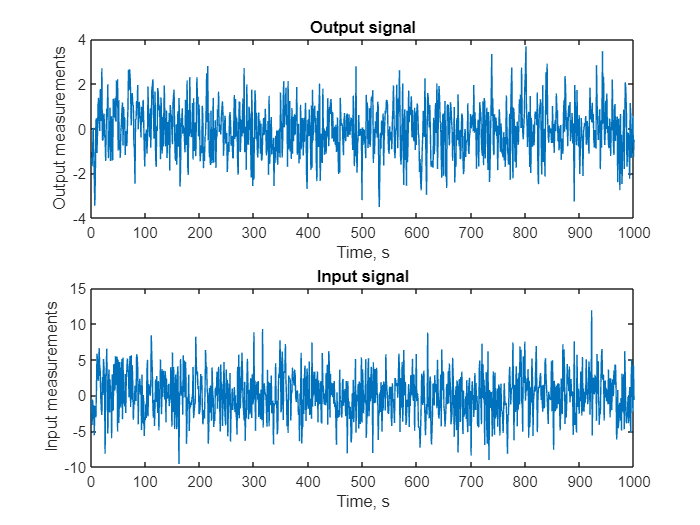

%%%%%%%%
% I cannot provide my own measurements as they are private
% Use your measured input and output signals or simulate them using the FIR
% modeling
%%%%%%%%

% Plot first 1000 samples of the input and output signals
subplot(211)
plot(1:1000,y(1:1000))
xlabel('Time, s');
ylabel('Output measurements');
title('Output signal');
subplot(212)
plot(1:1000,u(1:1000))
xlabel('Time, s');
ylabel('Input measurements');
title('Input signal');

#### 2. Define the required estimation algorithm:

The FIR model is described by the following equation:


$$y\left(t\right)=B\left(z^{-1} \right)u\left(t\right)+e\left(t\right)=b_1 u\left(t-1\right)+\cdots +b_n u\left(t-n\right)+e\left(t\right),$$


which in the linear regression form is:

$y\left(t\;\right)=\varphi^T \left(t\right)\theta +e\left(t\right)$,

where $\varphi \left(t\right)={\left\lbrack u\left(t-1\right)\cdots u\left(t-n\right)\right\rbrack }^T$, $\theta ={\left\lbrack b_1 \cdots b_n \right\rbrack }^T$, and $e\left(t\right)$ is the additive random error term. Our goal is to estimate $\overset{\wedge }{\theta} =\left\lbrack \overset{\wedge }{b_1 } \cdots \overset{\wedge }{b_n } \right\rbrack$, from which we will be able to compute the optimal predictor $\overset{\wedge }{y\left(t\right)}$. 

For the estimation of the unknown FIR parameters, we will use the Recursive Weighted Least Squares (RWLS) algorithm, namely, **RWLS III**, which employs the matrix inversion lemma and involves a forgetting factor $\lambda$. The RWLS III algorithm is described by the equations (1)-(4):

${S\left(t\right)}^{-1} =\frac{{S\left(t-1\right)}^{-1} }{\lambda }-\frac{{S\left(t-1\right)}^{-1} \varphi \left(t\right){\varphi \left(t\right)}^T {S\left(t-1\right)}^{-1} }{\lambda \left(\lambda +\varphi^T \left(t\right){S\left(t-1\right)}^{-1} \varphi \left(t\right)\right)}$  (1)

      $K\left(t\right)={S\left(t\right)}^{-1} \varphi \left(t\right)$  (2)      

$\varepsilon \left(t\right)=y\left(t\right)-\varphi^T \left(t\right)\overset{\wedge }{\theta \left(t-1\right)}$  (3)

$\overset{\wedge }{\theta \left(t\right)} =\overset{\wedge }{\theta \left(t-1\right)} +K\left(t\right)\varepsilon \left(t\right)$  (4),

where $S\left(t\right)=\sum_{k=1}^t \lambda^{t-k} \varphi \left(k\right){\varphi \left(k\right)}^T$, is the weighted covariance-like matrix of the regressors $\varphi \left(t\right)$ over time. The initial value of $S\left(t\right)$, $S\left(1\right)$, has been initialized to $\lambda *\alpha *I$ in the **"myRWLS_III.m"** function, where $\alpha ={10}^6$ and $I$ is an$\textrm{nxn}\;$identity matrix. In the  **"myRWLS_III.m"** function, $\overset{\wedge }{\theta \left(1\right)}$ is computed using the values of $S\left(1\right)$ and $\varphi^T \left(1\right)$, where the last has been computed by the "myPhi.m" function. This function computes the $\varphi^T \left(t\right)$ vector for the current $t$ value. In general, the **"myRWLS_III.m"** function takes as the input the measured values of input *u* and output *y*, and the forgetting factor $\lambda$, then iteratively estimates for the FIR parameters by solving the equations (1)-(4), so that the output is $\overset{\wedge }{\theta}$ and the covariance matrix $S$.

% Cross-validation of 5 folds taking only consecutive samples of the
% signals within a fold
num_folds = 5;
fold_size = floor(N/num_folds); 

max_order = 20; 
lambda_est = 1; % Forgetting factor for model estimation
lambda = 0.99; % Forgetting factor for parameter estimation and model validation
J_train = zeros(max_order,num_folds);
J_val = zeros(max_order,num_folds);

for fold = 1:num_folds
    
    val_startidx = (fold-1)*fold_size+1;
    if fold < num_folds
        val_endidx = fold*fold_size;
    else
        val_endidx = N; % Last fold takes remaining samples
    end
    
    validx = val_startidx:val_endidx;
    trainidx = setdiff(1:N, validx);
    
    % Splitting data into train and validation sets 
    utrain = u(trainidx);
    ytrain = y(trainidx);
    uval = u(validx);
    yval = y(validx);

    for n = 1:max_order
        [theta, ~] = myRWLS_III(ytrain, utrain, n, lambda);
        J_train(n,fold) = myCostFunc(ytrain, utrain, theta, lambda); % Computing the training cost function
        J_val(n,fold) = myCostFunc(yval, uval, theta, lambda); % Computing the validation cost function
    end
end

J_val = mean(J_val,2); % Averaging the validation cost values accross 5 folds

[value1, n_min1] = min(J_val); % Finding and printing the order corresponding to the lowest cost value
disp('min J - n');

min J - n


disp([value1, n_min1]);

    0.0250    3.0000



For estimating the model parameters and computing the cost function values, we use the cross-validation technique comprised of 5 folds. This helps to mitigate the overfitting of the estimated model. The **"myCostFunc.m" **function implements the weighted squared cost function of the residuals having the equation:


$$J\left(\theta \right)=\sum_{t=1}^N \lambda^{N-t} \varepsilon^2 \left(t\right)$$


For calculating the cost function values on the training and validation sets, we use $\lambda$ equal to 0.99. We run the algorithm across 5 folds and 20 different model orders, from 1 to 20, to plot the cost functions and check their behaviours - whether there is a sign of overfitting or not. From averaging the validation loss values across 5 folds in the code above, we observe that the minimum values corresponds to the model of the 3rd order **(n = 3) **(sometimes 4th order). In the plot below, we see that the validation loss is indeed decreasing up to n = 3 or 4, and then starts consistently increasing for the higher model orders. But looking at the cost function values is not a robust technique to estimate the FIR model's order; therefore, we will use some other more robust methods.  

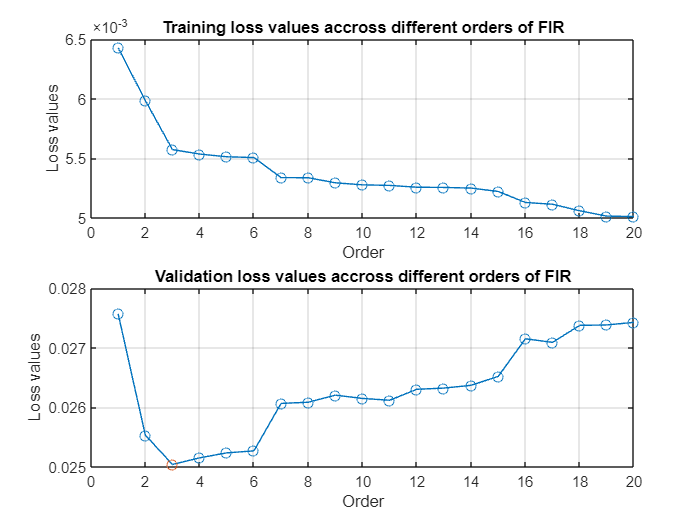

figure;
subplot(211)
plot(mean(J_train,2), '-o')
xlabel('Order');
ylabel('Loss values');
title('Training loss values accross different orders of FIR');
grid on; 
subplot(212)
plot(J_val, '-o')
hold on
plot(n_min1,J_val(n_min1),'o');
xlabel('Order');
ylabel('Loss values');
title('Validation loss values accross different orders of FIR');
grid on; 

#### 3. Estimate the model order:

**AIC**

To estimate the model order, we set the forgetting factor equal to 1. The first technique used for this purpose is the Akaike information criterion (AIC), which is implemented in the **"myAIC.m"** function. The AIC function penalizes the decrease of the cost function $J\left(\overset{\wedge }{\theta} \right)$ with increasing orders and has the following equation below:


$$\textrm{AIC}=\textrm{NlogJ}\left(\overset{\wedge }{\theta} \right)+2n$$


As we run the algorithm and plot the resulting AIC values for different orders, we identify that the lowest value corresponds to the model order equal to 3 or 4 (as indicated previously by the validation loss). We know that the AIC criterion can sometimes overestimate the order; therefore, by using some other complexity criterion, we have to see if the order of the model can indeed be a lower number. 

AIC = zeros(max_order, num_folds);

for fold = 1:num_folds
    
    val_startidx = (fold-1)*fold_size+1;
    if fold < num_folds
        val_endidx = fold*fold_size;
    else
        val_endidx = N; % Last fold takes remaining samples
    end
    
    validx = val_startidx:val_endidx;
    trainidx = setdiff(1:N, validx);
    
    utrain = u(trainidx);
    ytrain = y(trainidx);
    uval = u(validx);
    yval = y(validx);

    for n = 1:max_order
        [theta, ~] = myRWLS_III(ytrain, utrain, n, lambda_est); 
        AIC(n,fold)=myAIC(yval, uval, theta, lambda_est);
    end
end

AIC = mean(AIC,2);

[value2, n_min2] = min(AIC);
disp('min AIC - n');

min AIC - n


disp([value2, n_min2]);

  732.4306    3.0000



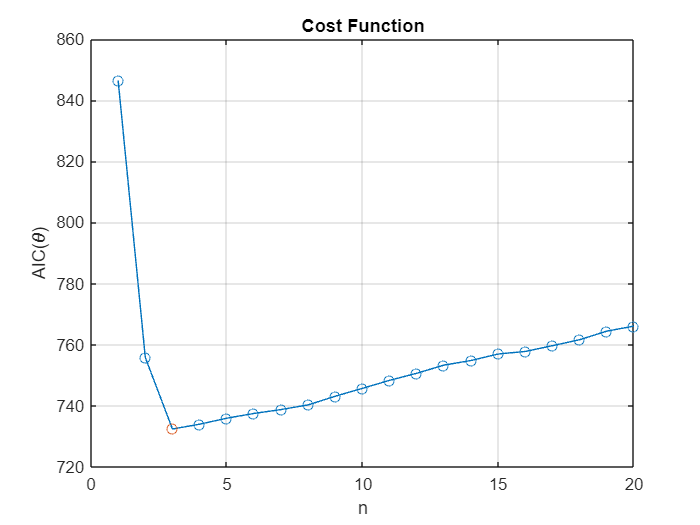

figure;
plot(AIC,'-o');
grid on;
hold on;
plot(n_min2,AIC(n_min2),'o');
ylabel('AIC(\theta)');
xlabel('n');
title('Cost Function');

**MDL**

The last complexity criterion that I am going to use is called the Minimum Description Length (MDL). The output of it almost always gives a lower model order and has the following equation:


$$\textrm{MDL}=\textrm{Nlog}\left(J\left(\overset{\wedge }{\theta} \right)\right)+\textrm{nlogN}$$


The MDL criterion eventually confirms that the FIR model is of order 3 and its cost function graph shows even a steeper increase than in AIC after n = 3. Thus, we assume the 3rd order of the model to construct our predictor and perform the validation process. 

MDL = zeros(max_order, num_folds);

for fold = 1:num_folds
    
    val_startidx = (fold-1)*fold_size+1;
    if fold < num_folds
        val_endidx = fold*fold_size;
    else
        val_endidx = N; % Last fold takes remaining samples
    end
    
    validx = val_startidx:val_endidx;
    trainidx = setdiff(1:N, validx);
    
    utrain = u(trainidx);
    ytrain = y(trainidx);
    uval = u(validx);
    yval = y(validx);

    for n = 1:max_order
        [theta, ~] = myRWLS_III(ytrain, utrain, n, lambda_est);
        MDL(n,fold) = myMDL(yval, uval, theta, lambda_est);
    end
end

MDL = mean(MDL,2);

[value3, n_min3] = min(MDL);
disp('min MDL - n');

min MDL - n


disp([value3, n_min3]);

  776.1949    3.0000



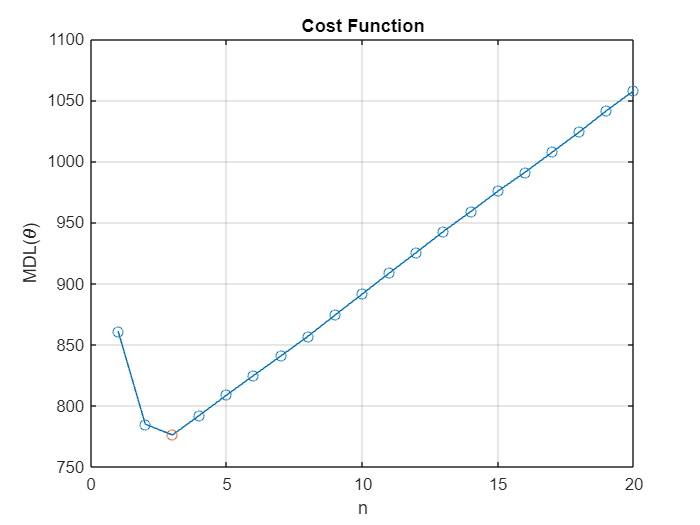

figure;
plot(MDL,'-o');
grid on;
hold on;
plot(n_min3,MDL(n_min3),'o');
ylabel('MDL(\theta)');
xlabel('n');
title('Cost Function');

#### 4. Validate the model:

For the found optimal model order (n_min3 = 3), we estimate the FIR model parameters using the entire dataset and store them in the theta_opt variable. We compute our vector of the residuals by subtracting our output obtained after FIR modeling from the observed (true) output. Now, this is the step of performing the **whiteness test** on our residuals to validate the model. For that we consider the sample variance $\overset{\wedge }{r_{\varepsilon } \left(0\right)}$ and the first *m *sample autocorrelations of the residuals $\varepsilon \left(t,\overset{\wedge }{\theta} \right)$, where under the hypothesis that $\varepsilon \left(t,\overset{\wedge }{\theta} \right)$ is the white process, the following must be true:


$$\overset{\wedge }{r_{\varepsilon } \left(0\right)} \;\underset{N\longrightarrow \infty }{\longrightarrow} {\sigma^2 }_w$$
                 
$$\overset{\wedge }{r_{\varepsilon } \left(\tau \right)} \;\underset{N\longrightarrow \infty }{\longrightarrow} 0,\;\tau =1,\cdots ,m$$


As a consequence, the statistical test value $x$ equals:


$$x=\frac{N\overset{\wedge }{r_{\varepsilon }^T } \overset{\wedge }{r_{\varepsilon } } \;\;}{\overset{\wedge }{r_{\varepsilon }^2 \left(0\right)} \;}\underset{N\longrightarrow \infty }{\longrightarrow} \sim {\chi_{\alpha } }^2 \left(m\right)$$


Following the conventions, we have chosen the number of autocorrelation samples m to be 20 and $\alpha$ to be 0.05. Below you see our estimated FIR parameters, the test statistic variable *x* and the chi-square critical value$\;{{\;\chi }_{0\ldotp 05} }^2$. As we observe, the value of x is lower than the value of chi-square, thus the null hypothesis is accepted meaning that the residuals are the white process, and our predictor is the optimal predictor of the given model. 

theta_opt = myRWLS_III(y, u, n_min3, lambda); % Computing the FIR parameters' estimates for the optimal n
disp("Parameters of the FIR model:")

Parameters of the FIR model:


disp(theta_opt)

    0.1294
    0.0862
    0.0852



y_hat = myHank(u,n_min3)*theta_opt;
residuals = y(n_min3+1:end) - y_hat; % Compute the residuals 

m = 20; % Number of samples of autocorrelation of the residuals to be considered
alpha = 0.05; 
[x, chi2_val]  = myValidation(residuals, m, alpha);

fprintf('Test Statistic x: %.2f\n', x);

Test Statistic x: 26.22


fprintf('Chi-square Critical Value: %.2f\n', chi2_val);

Chi-square Critical Value: 31.41


% Determine if we accept or reject the null hypothesis
if x <= chi2_val
    fprintf('Accept the null hypothesis: Residuals are a white process.\n')
else
    fprintf('Reject the null hypothesis: Residuals are not a white process.\n');
end

Accept the null hypothesis: Residuals are a white process.


This part of the code prints the covariance matrices S for different forgetting factors $\lambda$. I have chosen 4 different values that equal to 0.8, 0.9, 0.95, and 0.99. As we see from the output, as $\lambda$ increases, the values in the matrix S grow larger. This is because higher $\lambda$ means less forgetting, causing S to accumulate more information from the past data. When $\lambda$ is 0.99, the model incorporates almost all the past data equally, leading to larger entries; whereare, when $\lambda$ is 0.8, the model gives importance to a more recent data, thus having less memory and lower values inside the S matrix. The diagonal elements of S are larger than the off-diagonal elements, showing that each regressor's contribution to its own variance is stronger than its covariance with other regressors.

% Printing the parameters' covariance matrices for different forgetting
% factors
lambdas = [0.8 0.9 0.95 0.99]; 
num_lambdas = length(lambdas);
cov_matrices = cell(1, num_lambdas);

for i = 1:num_lambdas
    % Current forgetting factor
    lambda = lambdas(i);

    [~, S] = myRWLS_III(y,u,n_min3,lambda);
    cov_matrices{i} = S;

    fprintf('Lambda = %.2f:\n', lambdas(i));
    disp(cov_matrices{i}); % Display the matrix
    fprintf('\n')
end

Lambda = 0.80:


   77.0321  -37.2932    0.3812
  -37.2932   76.4693  -17.0229
    0.3812  -17.0229   51.4019



Lambda = 0.90:


  129.5547  -41.7403  -11.3725
  -41.7403  126.3311  -20.0727
  -11.3725  -20.0727  101.0926



Lambda = 0.95:


  227.4723  -45.1404  -13.1779
  -45.1404  222.7533  -22.5954
  -13.1779  -22.5954  197.2690



Lambda = 0.99:


   1.0e+03 *

    1.0350   -0.0388   -0.0026
   -0.0388    1.0295   -0.0153
   -0.0026   -0.0153    1.0041

